clear;
x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh(m);


s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);

iPar.mesh     = mesh;
iPar.quadType = 'QUADRATICMASS';
error         = IntegratorError(iPar);

Let's create now a Kernel filter based in Clément interpolators:

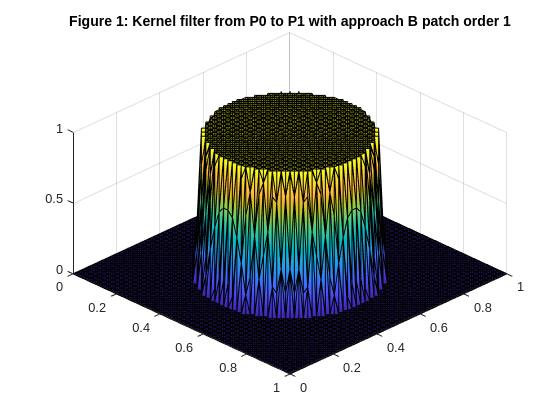

ss.filterType = 'AugmentedKernel';
ss.mesh       = mesh;
ss.test       = P0Function.create(mesh,1);
ss.trial      = P1Function.create(mesh,1);
ss.patchOrder = 1;
filter        = Filter.create(ss);
fP0P0B1       = filter.compute(fun,'QUADRATICMASS');
fP0P0B1.plot()
view(45,45)
title('Figure 1: Kernel filter from P0 to P1 with approach B patch order 1')

error.compute(fP0P0B1,fun)

ans =    0.002104881068073


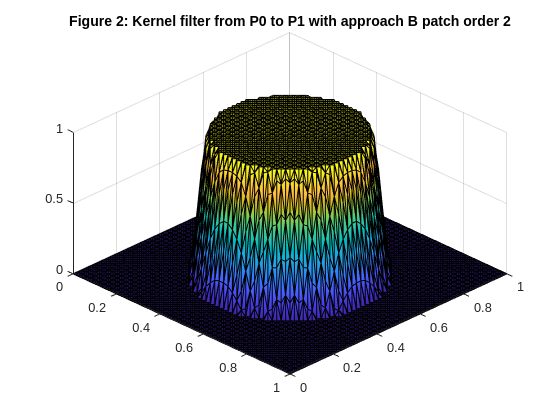



ss.patchOrder = 2;
filter        = Filter.create(ss);
fP0P0B2       = filter.compute(fun,'QUADRATICMASS');
fP0P0B2.plot()
view(45,45)
title('Figure 2: Kernel filter from P0 to P1 with approach B patch order 2')

error.compute(fP0P0B2,fun)

ans =    0.004149874678471


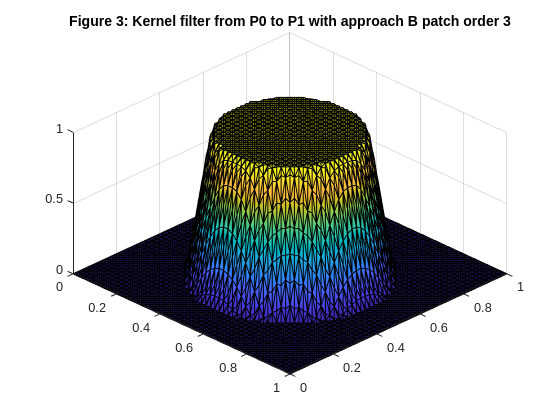



ss.patchOrder = 3;
filter        = Filter.create(ss);
fP0P0B3       = filter.compute(fun,'QUADRATICMASS');
fP0P0B3.plot()
view(45,45)
title('Figure 3: Kernel filter from P0 to P1 with approach B patch order 3')

error.compute(fP0P0B3,fun)

ans =    0.006276483897515


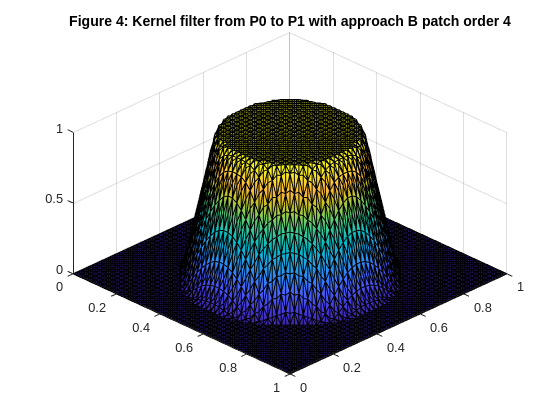



ss.patchOrder = 4;
filter        = Filter.create(ss);
fP0P0B4       = filter.compute(fun,'QUADRATICMASS');
fP0P0B4.plot()
view(45,45)
title('Figure 4: Kernel filter from P0 to P1 with approach B patch order 4')

error.compute(fP0P0B4,fun)

ans =    0.008409817767736


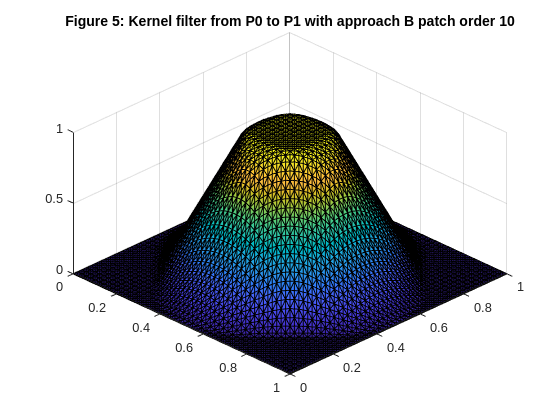



ss.patchOrder = 10;
filter        = Filter.create(ss);
fP0P0B10       = filter.compute(fun,'QUADRATICMASS');
fP0P0B10.plot()
view(45,45)
title('Figure 5: Kernel filter from P0 to P1 with approach B patch order 10')

error.compute(fP0P0B10,fun)

ans =    0.021615394276019
